# **RS-WISP-07-04: Defense100 Proposal Note - Inspection and Servicing SAT**

**WorekerInSpace**

**Hongseok Kim**

## Scope: 

  In this report, we will generate the Defense mission, configuration of Defense Satellite (Def_SAT), Inspection Satellite (Ins_SAT), and Servicing Satelltie (Serv_SAT), and Enemy Satellite.

  Centered by Defense Satellite (Nominal Orbit of 425 satellite of Korean Military), Defense Satellite and Inspection Satellite will rotate around the Derense Satellite or stay constant relative position.

  We will perform 3 mission Simulation

clear;clc;
addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions');

## Step 0: Add Epoch Information

%Initial Epoch Definition
Year = 2025;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = days(3);
steptime = 60;

startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
stopTime = startTime + duration;

scenario = satelliteScenario(startTime,stopTime,steptime);

## Step 1: Set up Def_SAT Orbit (One SAT from Constellation Orbit)

Def_SAT.a = 6946.773;
Def_SAT.e = 0.00014580;
Def_SAT.i = 45.4091;
Def_SAT.RAAN = 235.1785;
Def_SAT.AOP = 168.5505;
Def_SAT.TA = 191.5406;

mu = 398600.4415;
orbit_period = 2*pi* sqrt((Def_SAT.a)^3/mu)

orbit_period =      5.762164362513006e+03


## Step 2: Set up Ins_SAT and Serv_SAT orbit ($\pm 0\ldotp 1\deg$ TA)

Ins_SAT.a = Def_SAT.a;
Ins_SAT.e = Def_SAT.e;
Ins_SAT.i = Def_SAT.i;
Ins_SAT.RAAN = Def_SAT.RAAN;
Ins_SAT.AOP = Def_SAT.AOP;
Ins_SAT.TA = Def_SAT.TA+0.1;


Serv_SAT.a = Def_SAT.a;
Serv_SAT.e = Def_SAT.e;
Serv_SAT.i = Def_SAT.i;
Serv_SAT.RAAN = Def_SAT.RAAN; 
Serv_SAT.AOP = Def_SAT.AOP; 
Serv_SAT.TA = Def_SAT.TA-0.1;

Enem_SAT.a = Def_SAT.a;
Enem_SAT.e = Def_SAT.e;
Enem_SAT.i = Def_SAT.i;
Enem_SAT.RAAN = Def_SAT.RAAN + 0.5;
Enem_SAT.AOP = Def_SAT.AOP; 
Enem_SAT.TA = Def_SAT.TA;



[r_Def, v_Def] = kepler2ijk_hs(Def_SAT.a, Def_SAT.e, Def_SAT.i, Def_SAT.RAAN, Def_SAT.AOP, Def_SAT.TA);
[r_Ins, v_Ins] = kepler2ijk_hs(Ins_SAT.a, Ins_SAT.e, Ins_SAT.i, Ins_SAT.RAAN, Ins_SAT.AOP, Ins_SAT.TA);
[r_Serv, v_Serv] = kepler2ijk_hs(Serv_SAT.a, Serv_SAT.e, Serv_SAT.i, Serv_SAT.RAAN, Serv_SAT.AOP, Serv_SAT.TA);
[r_Enem, v_Enem] = kepler2ijk_hs(Enem_SAT.a, Enem_SAT.e, Enem_SAT.i, Enem_SAT.RAAN, Enem_SAT.AOP, Enem_SAT.TA);

## Step 2.1: Run Orbit Simulation

Orbit_propagator = 'SGP4';
SAT_config = satellite(scenario, [Def_SAT.a; Ins_SAT.a; Serv_SAT.a; Enem_SAT.a]*1000, ...
                                 [Def_SAT.e; Ins_SAT.e; Serv_SAT.e; Enem_SAT.e], ...
                                 [Def_SAT.i; Ins_SAT.i; Serv_SAT.i; Enem_SAT.i], ...
                                 [Def_SAT.RAAN; Ins_SAT.RAAN; Serv_SAT.RAAN; Enem_SAT.RAAN], ...
                                 [Def_SAT.AOP; Ins_SAT.AOP; Serv_SAT.AOP; Enem_SAT.AOP], ...
                                 [Def_SAT.TA; Ins_SAT.TA; Serv_SAT.TA; Enem_SAT.TA], ...
                                 Name = ["Def_SAT";"Ins_SAT";"Serv_SAT";"Enem_SAT"], ...
                                 OrbitPropagator = Orbit_propagator);

SAT_config(1).Orbit.LeadTime = orbit_period/2; SAT_config(2).Orbit.LeadTime = orbit_period/2; SAT_config(3).Orbit.LeadTime = orbit_period/2; SAT_config(4).Orbit.LeadTime = orbit_period/2;
SAT_config(1).Orbit.TrailTime = orbit_period/2; SAT_config(2).Orbit.TrailTime = orbit_period/2; SAT_config(3).Orbit.TrailTime = orbit_period/2; SAT_config(4).Orbit.TrailTime = orbit_period/2;
SAT_config(1).Orbit.LineColor = 'cyan'; 
SAT_config(2).Orbit.LineColor = 'g';
SAT_config(3).Orbit.LineColor = 'g';
SAT_config(4).Orbit.LineColor = 'r';
play(scenario)

## Step 3: Setup CircumNavigation Condition for INS and Serv

% N = 1; alpha = 0;
% [Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf, t_vector] = cirumNavigation(r_Def, v_Def, r_Ins, v_Ins, N, alpha);
% format long
% 
% delta_v_t_mat(1,:)
% 
% v_Ins = v_plus_ECI;
% 
% [Ins_SAT.a, Ins_SAT.e, Ins_SAT.i, Ins_SAT.RAAN, Ins_SAT.AOP, Ins_SAT.TA] = ijk2kepler_hs(r_Ins, v_Ins);
% 
% 
% [Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf, t_vector] = cirumNavigation(r_Def, v_Def, r_Serv, v_Serv, N, alpha);
% v_Serv = v_plus_ECI;
% 
% delta_v_t_mat(1,:)
% 
% 
% [Serv_SAT.a, Serv_SAT.e, Serv_SAT.i, Serv_SAT.RAAN, Serv_SAT.AOP, Serv_SAT.TA] = ijk2kepler_hs(r_Serv, v_Serv);

## Setup 3.1: Run Orbit Simulation

% Orbit_propagator = 'SGP4';
% SAT_config = satellite(scenario, [Def_SAT.a; Ins_SAT.a; Serv_SAT.a; Enem_SAT.a]*1000, ...
%                                  [Def_SAT.e; Ins_SAT.e; Serv_SAT.e; Enem_SAT.e], ...
%                                  [Def_SAT.i; Ins_SAT.i; Serv_SAT.i; Enem_SAT.i], ...
%                                  [Def_SAT.RAAN; Ins_SAT.RAAN; Serv_SAT.RAAN; Enem_SAT.RAAN], ...
%                                  [Def_SAT.AOP; Ins_SAT.AOP; Serv_SAT.AOP; Enem_SAT.AOP], ...
%                                  [Def_SAT.TA; Ins_SAT.TA; Serv_SAT.TA; Enem_SAT.TA], ...
%                                  Name = ["Def_SAT";"Ins_SAT";"Serv_SAT";"Enem_SAT"], ...
%                                  OrbitPropagator = Orbit_propagator);
% 
% SAT_config(1).Orbit.LeadTime = orbit_period/2; SAT_config(2).Orbit.LeadTime = orbit_period/2; SAT_config(3).Orbit.LeadTime = orbit_period/2; SAT_config(4).Orbit.LeadTime = orbit_period/2;
% SAT_config(1).Orbit.TrailTime = orbit_period/2; SAT_config(2).Orbit.TrailTime = orbit_period/2; SAT_config(3).Orbit.TrailTime = orbit_period/2; SAT_config(4).Orbit.TrailTime = orbit_period/2;
% SAT_config(1).Orbit.LineColor = 'cyan'; 
% SAT_config(2).Orbit.LineColor = 'g';
% SAT_config(3).Orbit.LineColor = 'g';
% SAT_config(4).Orbit.LineColor = 'r';
% play(scenario)

## Step 4: Inspection Satellite Approach for Enemy Satellite

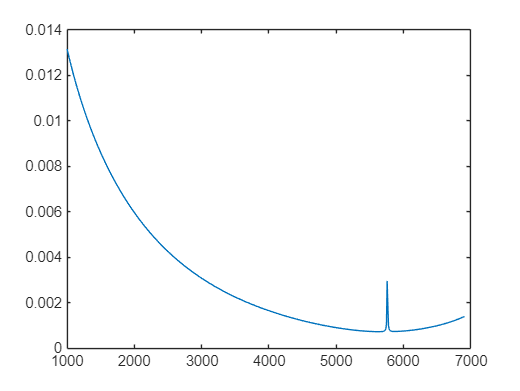

tf_candidate =1000:10:orbit_period*1.2;
Delta_v_grid = zeros(length(tf_candidate),1);
delta_r_final = [0,0,0]';

   for tf_index = 1:length(tf_candidate)
       tf = tf_candidate(tf_index);

        [Delta_v_0, ...
         Delta_v_f, ...
         delta_r_t_mat, ...
         delta_v_t_mat, ...
         v_plus_ECI, ...
         t_vector] = two_impulse_rendezvous_targeting(r_Def, v_Def, r_Ins, v_Ins, ...
                                                      delta_r_final,tf);

      Delta_v_grid(tf_index) = norm(Delta_v_0);
   end

plot(tf_candidate, Delta_v_grid)